%qdot = 0.5 * q * [0; omega]
clear; clc;

omega = [0, 30, 0]; %deg/s, y is pitch
omegarad = deg2rad(omega); %Kinematic eq. is valid for radians

P = @(q) 0.5 * quatmultiply(q, [0, omegarad])

P = function_handle with value:
    @(q)0.5*quatmultiply(q,[0,omegarad])


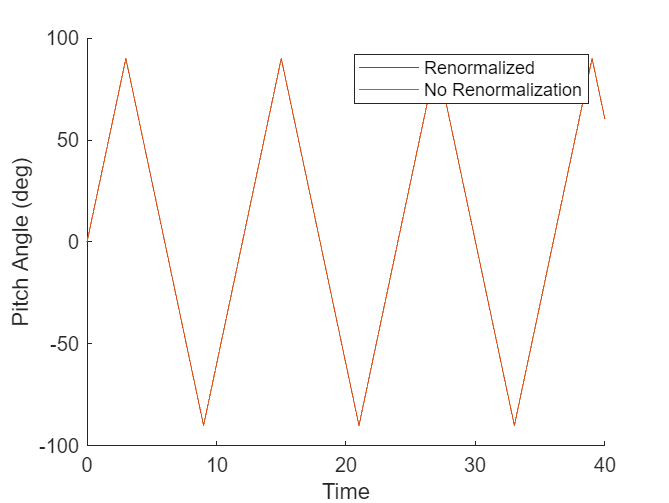


q0 = [1, 0, 0, 0]; %Initial Value
dt = .001; %time step, seconds
tmax = 40; %sec
nt = tmax/dt; %number of steps

%interval and solution arrays, one for proper renormalization, the other
%without to demonstrate drift.
tvals = transpose(0:dt:tmax);
q_sol = zeros(nt,4);
q_drift = zeros(nt, 4);
q_sol(1,:) = q0;
q_drift(1,:) = q0;

%RK4 Numerical Integrator
for i=1:nt
    %Drifted values
    D1 = P(q_drift(i,:));
    D2 = P(q_drift(i,:) + dt/2 * D1);
    D3 = P(q_drift(i,:) + dt/2 * D2);
    D4 = P(q_drift(i,:) + dt * D3);
    

    %Driftless
    P1 = P(q_sol(i,:));
    P2 = P(q_sol(i,:) + dt/2 * P1);
    P3 = P(q_sol(i,:) + dt/2 * P2);
    P4 = P(q_sol(i,:) + dt * P3);
    
    q_drift(i+1,:) = q_drift(i,:) + (dt/6) * (D1 + 2*(D2 + D3) + D4);

    %Normalize to ensure quaternion lies on unit sphere
    placeholder = q_sol(i,:) + (dt/6) * (P1 + 2*(P2 + P3) + P4);
    q_sol(i+1,:) = placeholder/norm(placeholder);
end

%Plot pitch angles for both
eul = quat2eul(q_sol);
pitch_driftless = rad2deg(eul(:,2));
eul = quat2eul(q_drift);
pitch_drift = rad2deg(eul(:,2));

% pitch_driftless = zeros(nt+1,1);
% pitch_drift = zeros(nt+1,1);
% for i=1:nt+1
%     [phi, theta, psi] = dcm2euler(quat2dcm(q_sol(i,:)));
%     pitch_driftless(i) = theta;
%     [phi, theta, psi] = dcm2euler(quat2dcm(q_drift(i,:)));
%     pitch_drift(i) = theta;
% end
% 
% pitch_driftless = real(pitch_driftless);

figure
hold on
plot(tvals, pitch_driftless)
plot(tvals, pitch_drift)
legend("Renormalized", "No Renormalization")
xlabel("Time")
ylabel("Pitch Angle (deg)")
hold off



%Documentation: I used my MATH 346 Notes to refresh myself on numerical
%integration in MATLAB in general and on RK4.